# Thermoeconomic Analysis Demo

Use `ThermoeconomicAnalysis` function to compute the exergy cost of a plant

### Select and read the data model file

filename="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\cgam\cgam_model.json";
data=ReadDataModel(filename);

### Select the parameters

States=string(data.StateNames);
State=char(States(3));
CostTables=cType.DEFAULT_COST_TABLES;
if data.isResourceCost
    Samples=string(data.SampleNames);
    ResourceSample=char(Samples(1));
    CostTables='ALL';
end

### Make Cost Analysis

Compute cost and show the results

res=ThermoeconomicAnalysis(data,'State',State, ...
    'CostTables',CostTables,'ResourceSample',ResourceSample,'Show',true);


Process Exergy Cost - ETG87

Key         P*(MW)    Pin*(MW)    Pex*(MW)      F*(MW)      R*(MW)
———————————————————————————————————————————————————————————————————
COMB       173.568     165.735       7.833     170.830       2.738
CMP         55.548      52.637       2.911      55.216       0.332
TRB        107.226     102.217       5.009     107.048       0.178
APH         41.682      39.498       2.184      41.365       0.317
HRSG        21.590      20.615       0.974      21.590       0.000
STCK         3.565       3.404       0.161       3.565       0.000


Process Unit Exergy Cost - ETG87

Key        kP*(J/J)    kin*(J/J)    kex*(J/J)     kF*(J/J)     kR*(J/J)       k(J/J)
—————————————————————————————————————————————————————————————————————————————————————
COMB         1.6535       1.5789       0.0746       1.3609       0.0261       1.1958
CMP          1.8934       1.7942       0.0992       1.7337       0.0113       1.0856
TRB          1.7337       1.6527       0.0810       1.65

### Show the default thermoeconomic analysis graph

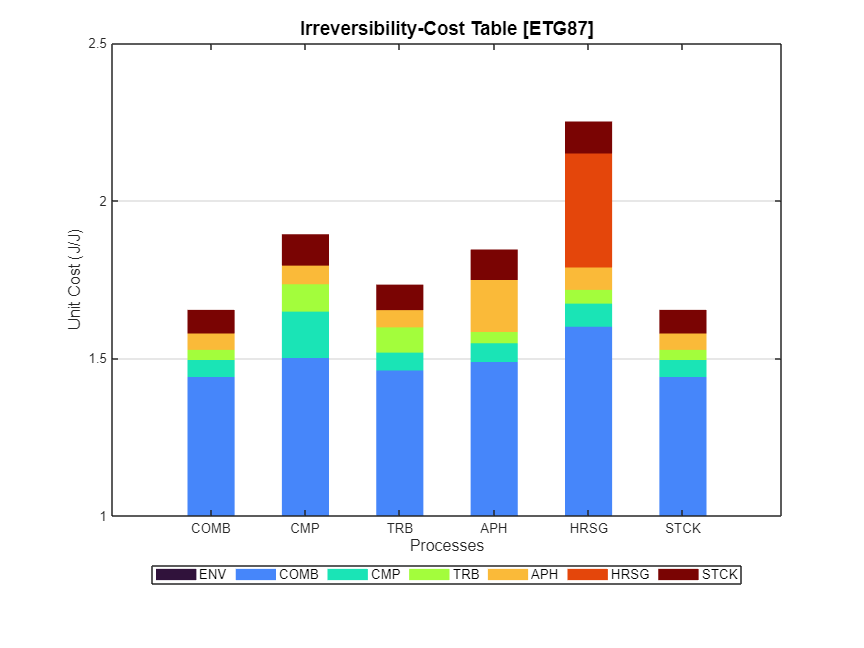

ShowGraph(res);

### Additional Help Information

help ThermoeconomicAnalysis

 ThermoeconomicAnalysis - Perform the termoeconomic analysis of a plant state.
    Calculate the exergy cost, Fuel-Product and Irreversibility-Cost tables.
     If the data model has information on resource costs, generalised costs can be calculated; otherwise, only direct costs can be calculated.
     With the option 'CostTables', we choose the type of costs we want to calculate. 
     With the option 'ResourceSample', we choose the resource cost sample data.
 
    Syntax
      res=ThermoeconomicAnalysis(data,Name,Value)
 
    Input Arguments
  	  data - cDataModel object which contains the data model
 
    Name-Value Arguments
      State - Thermoeconomic state id. If missing first sample is taken
        array char | string
      CostTables - Indicate which cost tables are calculated
        'DIRECT' calculates direct exergy cost tables
        'GENERALIZED' calculates generalized exergy cost tables
        'ALL' calculate both kind of tables
      